% 绘制 SVM 分类模型的后验概率区域
% 此示例说明如何预测 SVM 模型在观测网格上的后验概率，然后绘制该网格上的后验概率。绘制后验概率会显现出决策边界。
% 
% 加载 Fisher 鸢尾花数据集。使用花瓣长度和宽度训练分类器，并从数据中删除海滨锦葵物种。

load fisheriris
classKeep = ~strcmp(species,'virginica');
X = meas(classKeep,3:4);
y = species(classKeep);
% 使用数据训练 SVM 分类器。指定类的顺序是很好的做法。

SVMModel = fitcsvm(X,y,'ClassNames',{'setosa','versicolor'});
% 估计最佳分数转换函数。

rng(1); % For reproducibility
[SVMModel,ScoreParameters] = fitPosterior(SVMModel); 

% Warning: Classes are perfectly separated.
% The optimal score-to-posterior transformation is a step function.
ScoreParameters

ScoreParameters = struct with fields:
                        Type: 'step'
                  LowerBound: -0.8431
                  UpperBound: 0.6897
    PositiveClassProbability: 0.5000


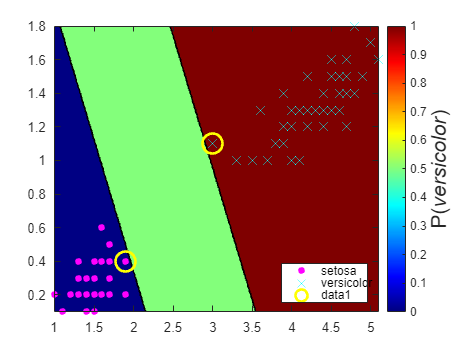

% ScoreParameters = struct with fields:
%                         Type: 'step'
%                   LowerBound: -0.8431
%                   UpperBound: 0.6897
%     PositiveClassProbability: 0.5000

% 最佳分数转换函数是阶跃函数，因为类是可分离的。
% ScoreParameters 的字段 LowerBound 和 UpperBound 指示
% 与类分离超平面（边距）内观测值对应的分数区间的下端点和上端点。
% 没有训练观测值落在边距内。
% 如果区间中有一个新分数，则软件会为对应的观测值分配一个正类后验概率，
% 即 ScoreParameters 的 PositiveClassProbability 字段中的值。

% 在观测到的预测变量空间中定义一个数值网格。
% 预测该网格中每个实例的后验概率。

xMax = max(X);
xMin = min(X);
d = 0.01;
[x1Grid,x2Grid] = meshgrid(xMin(1):d:xMax(1),xMin(2):d:xMax(2));

[~,PosteriorRegion] = predict(SVMModel,[x1Grid(:),x2Grid(:)]);
% 绘制正类后验概率区域和训练数据。

figure;
contourf(x1Grid,x2Grid,...
        reshape(PosteriorRegion(:,2),size(x1Grid,1),size(x1Grid,2)));
h = colorbar;
h.Label.String = 'P({\it{versicolor}})';
h.YLabel.FontSize = 16;
caxis([0 1]);
colormap jet;

hold on
gscatter(X(:,1),X(:,2),y,'mc','.x',[15,10]);
sv = X(SVMModel.IsSupportVector,:);
plot(sv(:,1),sv(:,2),'yo','MarkerSize',15,'LineWidth',2);
axis tight
hold off

% Figure contains an axes.
% The axes contains 4 objects of type contour, line. 
% These objects represent setosa, versicolor.

% 在二类学习中，如果类是可分离的，则有三个区域：
% 一个是包含正类后验概率为 0 的观测值的区域，
% 另一个是包含正类后验概率为 1 的观测值的区域，
% 还有一个是包含具有正类先验概率的观测值的区域。